dataDir = fullfile('./', 'Daten', 'Galaxies'); 
ellipticalDir = fullfile(dataDir, 'elliptic');
spiralDir = fullfile(dataDir, 'spiral');
irregularDir = fullfile(dataDir, 'irregular');

lbl_e(1:268) = categorical("elliptic");
lbl_e(269:268+233) = categorical("spiral");
lbl_e(268+233+1:1076) = categorical("irregular");



imds = imageDatastore(dataDir, "IncludeSubfolders", true, "Labels", lbl_e);

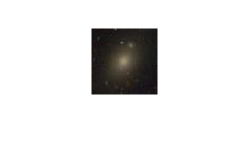

img_e = readimage(imds, 1);
imshow(img_e);

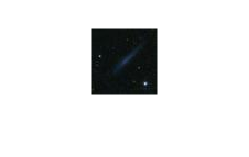

img_s = readimage(imds, 269);
imshow(img_s);

[imds_train, imds_test] = splitEachLabel(imds, 0.8);


Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       26.56% |       1.2220 |          0.0100 |
|       4 |          50 |       00:00:01 |       81.25% |       0.5617 |          0.0100 |
|       8 |         100 |       00:00:02 |       82.81% |       0.4619 |          0.0100 |
|      12 |         150 |       00:00:03 |       84.38% |       0.3773 |          0.0100 |
|      16 |         200 |       00:00:04 |       85.94% |       0.3485 |          0.0100 |
|      20 |         250 |       00:00:05 |       89.06% |       0.2910 |          0.0100 |
|      24 |         300 |  

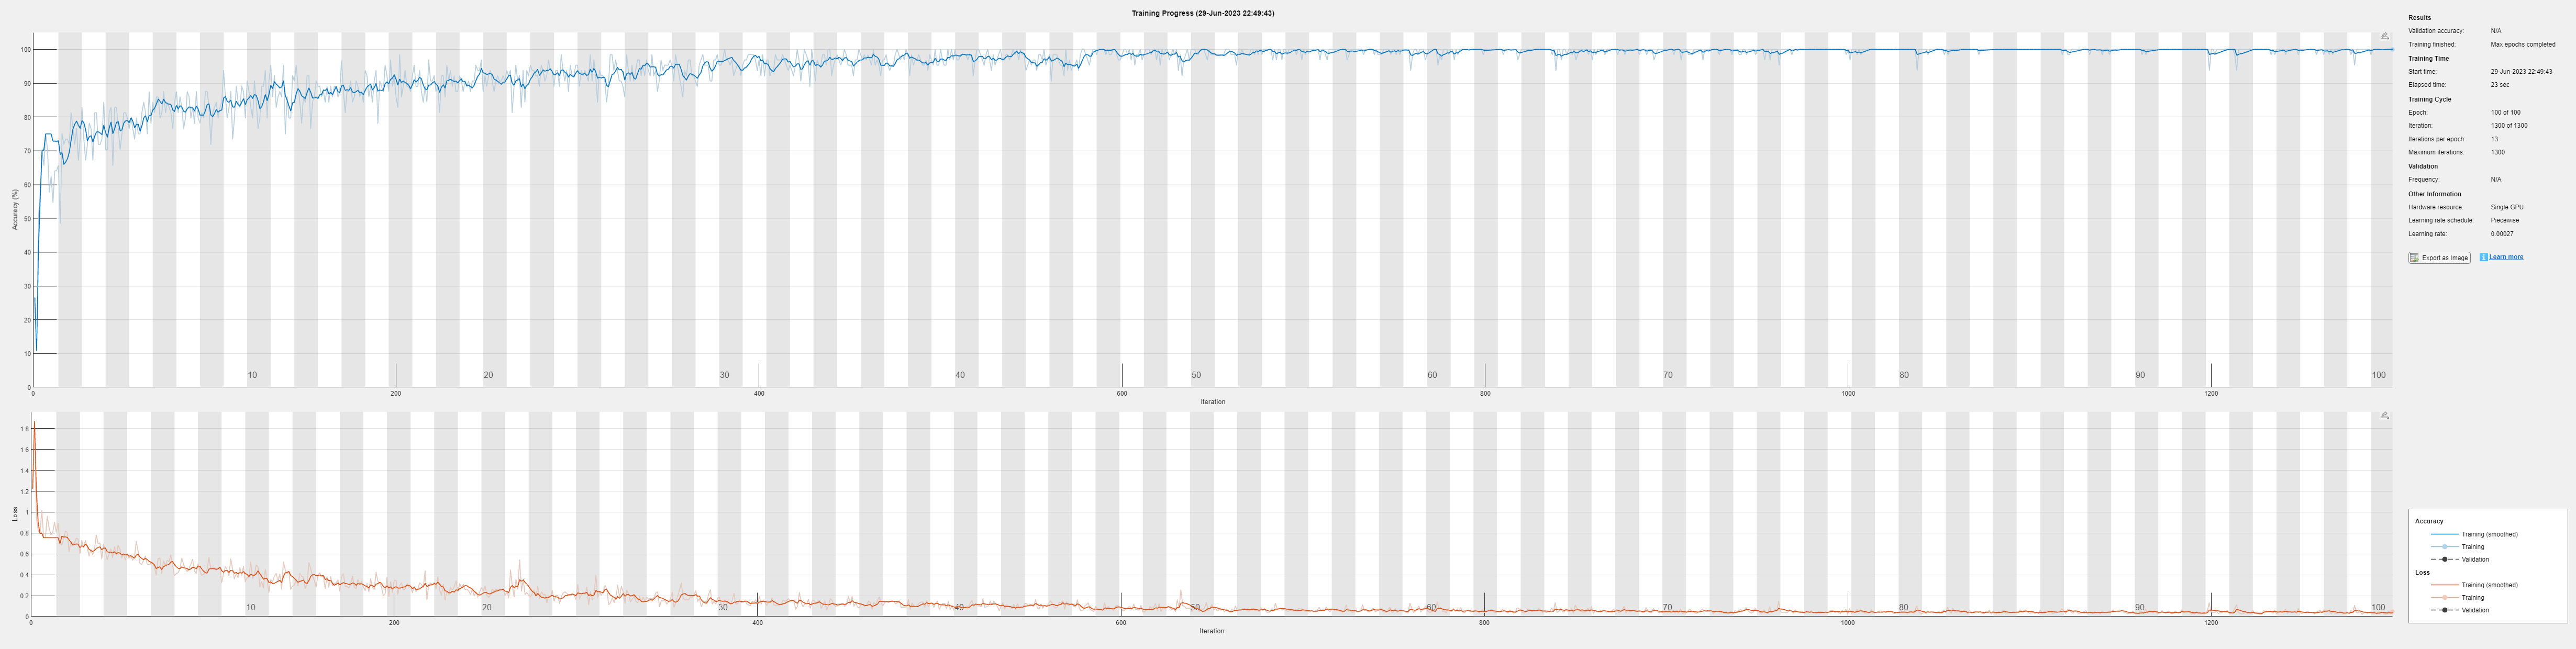

lambda = 1e-8;
layers = [
    imageInputLayer([60 60 3])
    convolution2dLayer(8, 96)
    reluLayer
    averagePooling2dLayer(3)
    fullyConnectedLayer(24)
    reluLayer
    fullyConnectedLayer(3)
    batchNormalizationLayer
    softmaxLayer
    classificationLayer
];
options = trainingOptions('adam', 'MaxEpochs', 100, 'L2Regularization', lambda, ...
    'MiniBatchSize', 64, 'Plots', 'training-progress', 'Shuffle', 'every-epoch', 'InitialLearnRate', 0.01, ...
    'LearnRateSchedule', 'piecewise', 'LearnRateDropPeriod', 25, 'LearnRateDropFactor', 0.3);
net_gala = trainNetwork(imds_train, layers, options);

tic
[pred, mat] = classify(net_gala, imds_test);
toc

Elapsed time is 0.145378 seconds.



testErr_gala = sum(pred ~= imds_test.Labels) / length(imds_test.Labels);

aug = imageDataAugmenter('RandRotation', [0, 120], ...
   'RandScale', [0.5, 1.2]);

augimds = augmentedImageDatastore([60 60 3], imds_train, 'DataAugmentation',aug);
entire_datastore = combine(imds_train, augimds)

entire_datastore =   CombinedDatastore with properties:

      UnderlyingDatastores: {[1×1 matlab.io.datastore.ImageDatastore]  [1×1 augmentedImageDatastore]}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]


Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       39.06% |       1.2201 |          0.0100 |
|       4 |          50 |       00:00:02 |       82.81% |       0.5395 |          0.0100 |
|       8 |         100 |       00:00:03 |       78.12% |       0.4807 |          0.0100 |
|      12 |         150 |       00:00:04 |       87.50% |       0.4117 |          0.0100 |
|      16 |         200 |       00:00:05 |       92.19% |       0.2576 |          0.0100 |
|      20 |         250 |       00:00:06 |       89.06% |       0.2641 |          0.0100 |
|      24 |         300 |  

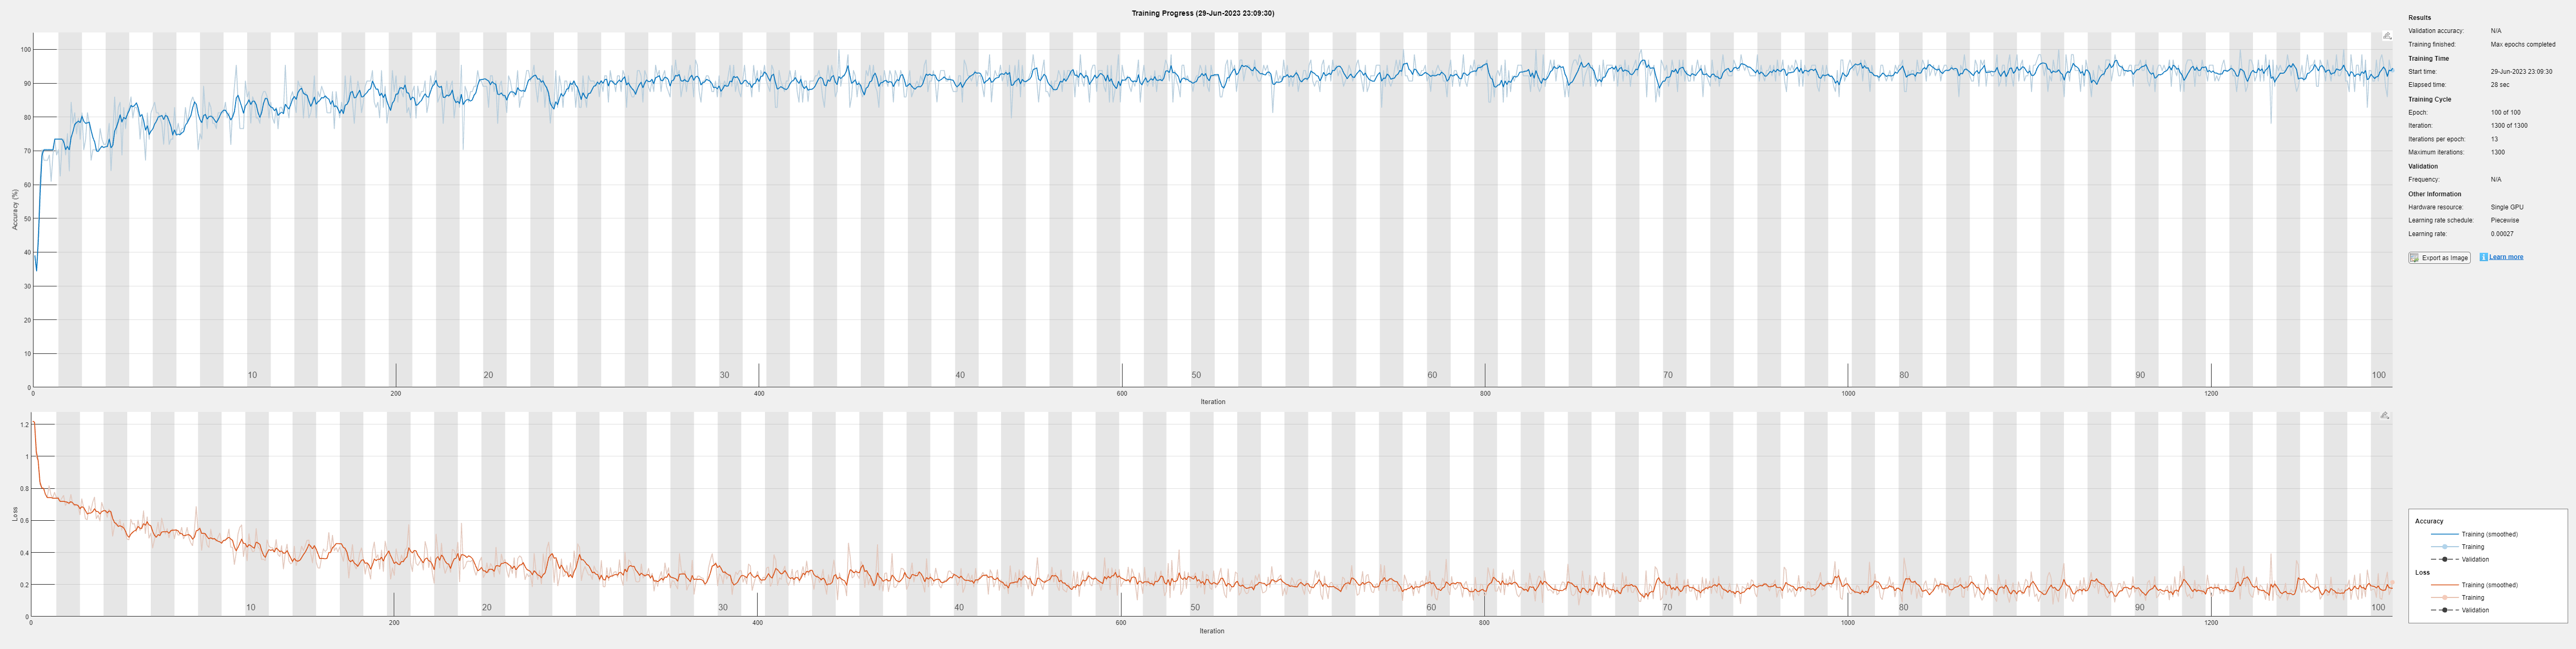

net_gala_aug = trainNetwork(augimds, layers, options);

tic
[pred, mat] = classify(net_gala_aug, imds_test);
toc

Elapsed time is 0.193574 seconds.



testErr_gala_aug = sum(pred ~= imds_test.Labels) / length(imds_test.Labels);

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       34.38% |       1.4972 |          0.0100 |
|       2 |          50 |       00:00:02 |       62.50% |       0.7216 |          0.0100 |
|       4 |         100 |       00:00:04 |       71.88% |       0.6228 |          0.0100 |
|       6 |         150 |       00:00:05 |       84.38% |       0.4842 |          0.0100 |
|       8 |         200 |       00:00:07 |       84.38% |       0.5276 |          0.0100 |
|      10 |         250 |       00:00:09 |       87.50% |       0.4446 |          0.0100 |
|      12 |         300 |  

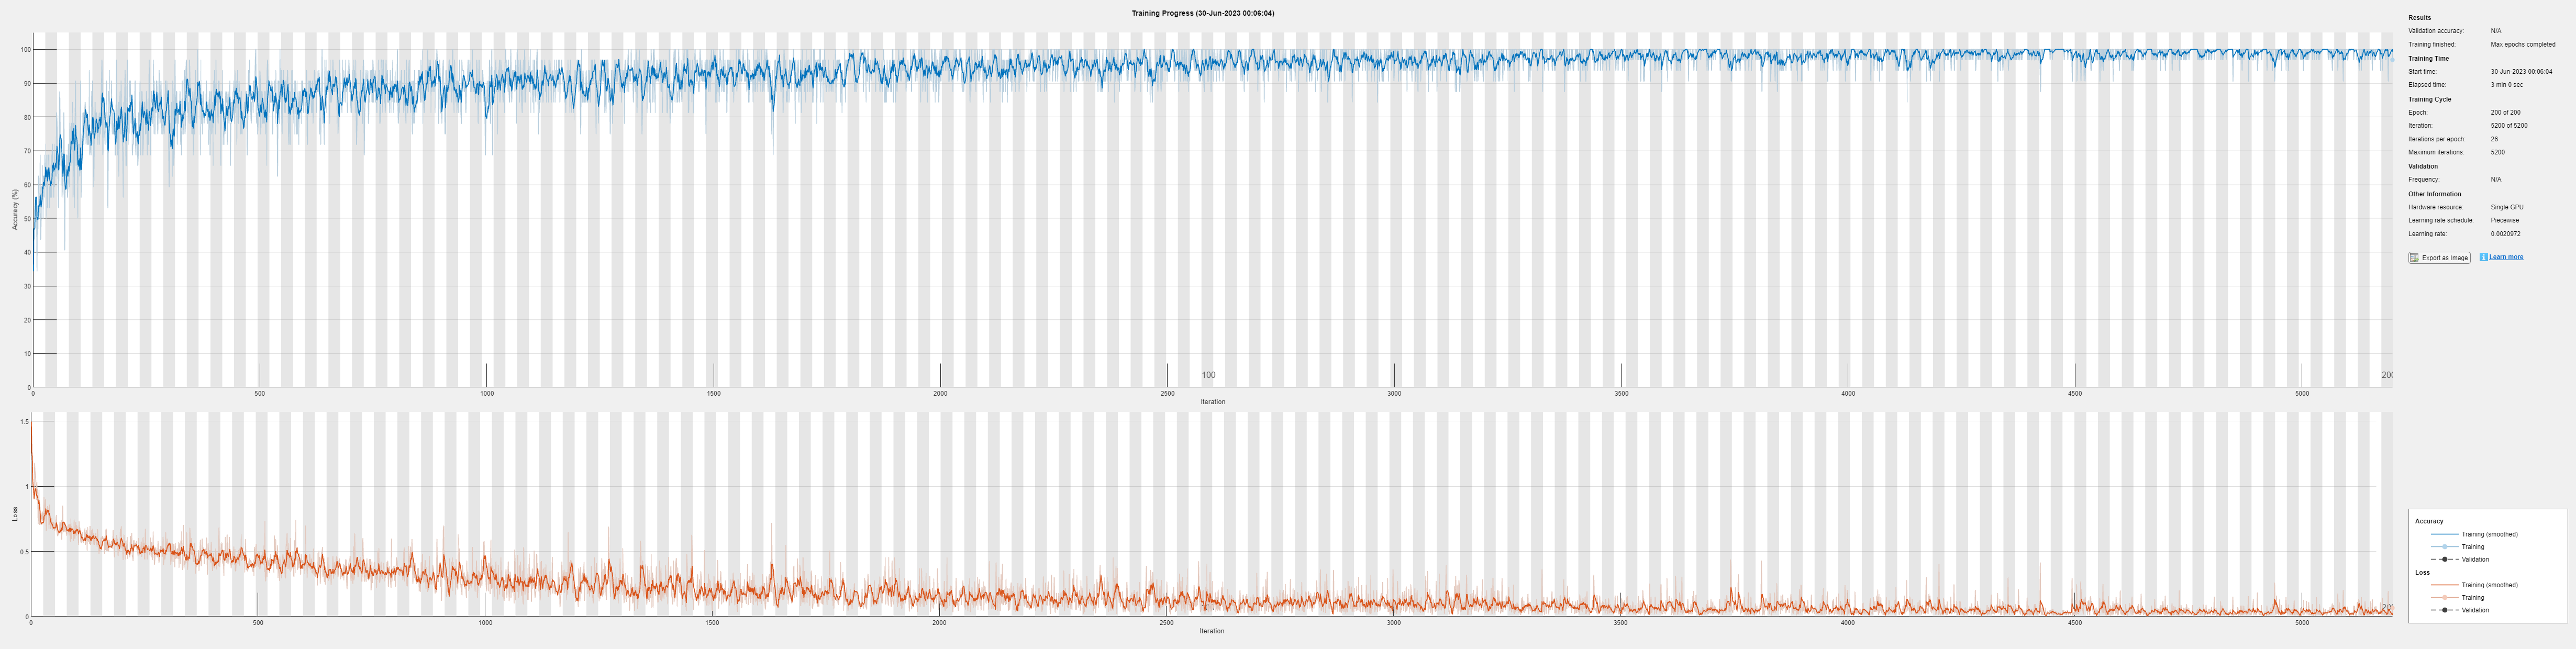

layers_custom = [
    imageInputLayer([60 60 3])
    convolution2dLayer(6, 32, "Padding", "same")
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    convolution2dLayer(8, 64, "Padding", "same")
    reluLayer
    maxPooling2dLayer(4, "Stride", 2)
    convolution2dLayer(8, 128, "Padding", "same")
    reluLayer
    maxPooling2dLayer(6, "Stride", 2)
    convolution2dLayer(8, 512, "Padding", "same")
    reluLayer
    maxPooling2dLayer(5, "Stride", 2)
    convolution2dLayer(12, 512, "Padding", "same")
    reluLayer
    dropoutLayer
    fullyConnectedLayer(1024)
    reluLayer
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(3)
    batchNormalizationLayer
    softmaxLayer
    classificationLayer
];
options_custom = trainingOptions('sgdm', 'MaxEpochs', 200, 'L2Regularization', lambda, ...
    'MiniBatchSize', 32, 'Plots', 'training-progress', 'Shuffle', 'every-epoch', 'InitialLearnRate', 0.01, ...
    'LearnRateSchedule', 'piecewise', 'LearnRateDropPeriod', 25, 'LearnRateDropFactor', 0.8);
net_gala_aug_custom = trainNetwork(augimds, layers_custom, options_custom);

tic
[pred, mat] = classify(net_gala_aug_custom, imds_test);
toc

Elapsed time is 0.231033 seconds.



testErr_gala_aug_custom = sum(pred ~= imds_test.Labels) / length(imds_test.Labels);